clc, clear vars, close all


## **Grabar un audio por el micrófono**

dlg_title = 'Grabar audio - micrófono';
prompt = { 'Frec. Muestreo:','Bits/muestra:', 'Núm. Canales:'};
num_lines = 1;
defaultans = {'44100', '16','1'};

answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

Fs1=str2num(answer{1});    % Frecuencia de muestreo   
nBit=str2num(answer{2});   % Número de bits por muestra
nChan=str2num(answer{3});   % Número de canales


aud1 = audiorecorder(Fs1,nBit,nChan); % Crear un objeto audiorecorder

% Crear un objeto uiprogressdlg con título e icono

fig = uifigure;

tRec=3; % Tiempo de grabación en s.

d = uiprogressdlg(fig,'Title',['Grabando audio (' num2str(tRec) ' seconds)'], 'Icon', "RecordAudio.jpg");

disp('Iniciando la grabación...');

Iniciando la grabación...



d.Message = sprintf('Hable ahora!! %.1f segundos', 0.1);

recordblocking(aud1, tRec); % Grabar  audio

% Actualizar la barra de avance y el mensaje cada 0.1 segundos
delta=0.1;
for i = 0.2:delta:tRec-delta
    d.Value = i/tRec;
    d.Message = sprintf('Tiempo transcurrido: %.1f segundos', i);
    pause(0.1);
end
% Cerrar el diálogo de progreso

close(d);
close(fig)

%disp('Fin de la grabación.');

y = getaudiodata(aud1); % Obtener los datos de la señal
audiowrite('miAudio.wav',y,Fs1); % Guardar los datos en un archivo WAV


## Visualizar la señal de audio - micrófono

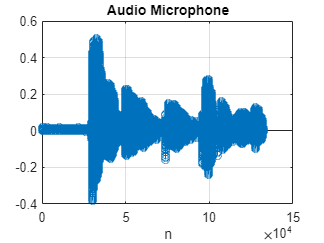

n = 0:length(y)-1;
stem(n,y); grid on; title('Audio Microphone'); xlabel('n')

## **Leer Archivo de Audio**

[filename, pathname] = uigetfile('*.*', 'Seleccione un archivo de audio'); % Seleccionar el archivo de audio
[y,Fs] = audioread(fullfile(pathname,filename)); % Leer el archivo de audio

## **Reproducir el Audio**

sound(y,Fs);% Reproducir el audio

ans =   audioplayer with properties:

       SampleRate: 44100
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 132300
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


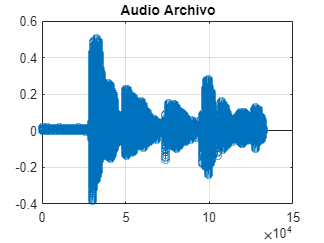

%t = (0:length(y)-1)/Fs; % Crear un vector de tiempo
n = 0:length(y)-1; % Crear un vector de instantes 

% Visualizar la señal 
figure; stem(n,y);title('Audio Archivo');grid on 